# Analysis 1

Testing out Cdt1 Tet-One construct

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\A35_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

conditions = { 
    '50 uM',2,4:5,1:16;     
    '10 uM',2,6:7,1:16; 
 
};

S = loadData_A35(conditions, dataDir);


**Different fluorophores and bleaching**

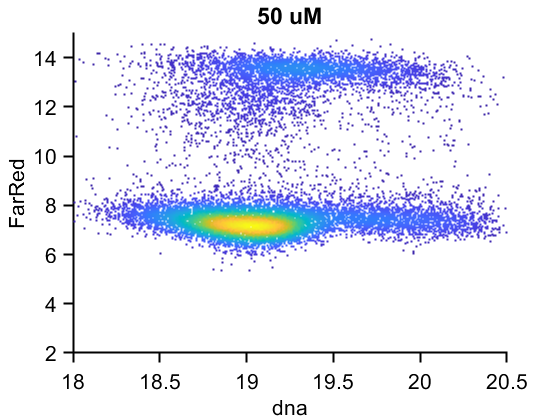

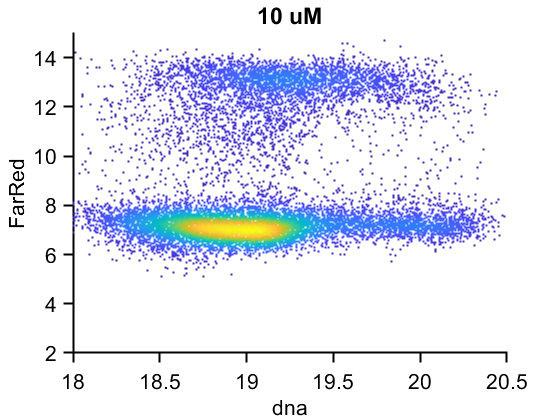

conds = [1:2];

xval = 'dna';
%xbg = [xval 'bg'];
yval = 'FarRed';
%ybg = [yval 'bg'];

gateVals = {};
rangeVals = {[2^6 2^14]}; 


for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  log2(S(condition).(yval));
    
    totalGate = true(size(xdata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
    %downsample = 5000;
%     xmin = prctile(xdata,1); xmax = prctile(xdata,99.5);
%     ymin = prctile(ydata,1); ymax = prctile(ydata,99.5);
%     ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
%     %ind = randsample(length(xdata),downsample);
%     xdata = xdata(ind); ydata = ydata(ind);
%     
    figure,
    dscatter(xdata,ydata);
    ylabel(yval);xlabel(xval);
    title(conditions{condition,1});
   xlim([18 20.5]); 
   ylim([2 15]);

    
end

**Compare histograms **

conds = [1 2];

yval = 'FarRed';

gateVals = {};
rangeVals = {[2^3 Inf], [0 2^20]}; 

data = {};

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'color','colormap','noerror','xlabel','log2[EdU (RFU)]','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


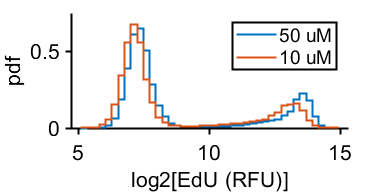

legend(conditions(conds,1))
% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\eduhists.pdf'])

% vline([ 6.75 10])
data

data = 1×2 cell array
    {16439×1 double}    {15571×1 double}
